% -------------------------------------- % 
%          APDS - Trabalho 04            %
%      Joao Victor Colombari Carlet      %
% -------------------------------------- % 

% Questao 01 %

%% 

close all 
clear all


## Definicoes

Np=480000; % Aqui capturo 10 segundos de track 
fs=48000;
ts=1/fs;

## Desenvolvimento

Minha proposta é apresentar um problema real para cada topologia de filtro e saná-los mediante aplicação. 

Para tanto vou definir o que chamarei de "As tres aflições do produtor musical". 

A primeira aflição será o ruído branco. A segunda, um ruído tipo hum. A terceira, um ruído hiss. 

Cada aflição será sanada utilizando uma topologia de filtro que será projetada utilizando o Filter Design Tool do Matlab.

% Importando a linha de violao do meu amigo Joao Luccas
[y,fs]=audioread('/Users/joaovitor/Documents/MATLAB/Monica/APDS_T2/Audio/violao.WAV');

R=y(1:Np);                    % 10 segundos de track

% Gerando vetor tempo
x=linspace(0, length(y)/(48000), length(y));
x=x(1:Np);

%% TF para auxiliar a visualizacao

% A definicao de k (da DTF) vem da definicao do comando fft. Ja que o comando 
% calcula com X[k] para (k-1), o range de vs q a DTF calcula comeca em 0 e
% vai ate quase 1 (1-1/Np). Ja que o k deve ter Np pontos:

k=(0:1:Np-1);   

% Mas, como disse, esse k so eh util para valores de 0 a Np. Se quiser
% utilizar o vetor para construir algo que mostre a TF, tenho transladar
% com Np/2, encaixando o vetor no primeiro periodo da TF, pondendo entao
% usar para construi-la.

ksh=k-Np/2;

% O v da minha DTFT é um vetor de Np pontos mas que vai de 0 ate 1. Entao
% eh so usar a mesma definicao, ajeitando os valores.

v=k/Np;

% Se eu quiser plotar a DTFT de menos meio a meio DEVO usar o vetor v
% transladado, de maniera a adequa-lo no periodo de interesse.

vsh=ksh/Np;

% Para o vetor de frequencias, acaba ficando como no Trabalho 1. La fiz a
% mesma coisa que vou fazer aqui, arrumando o vetor que vai de -meio a meio
% com o fs para ai sim poder construir minha TF.

f=vsh*fs;

% Para criar a TF vou usar o FFT no meu vetor da x(t)

X_DFT_R=fft(R);

% Isso entao calculou a DTF que ta indo de 0 a 1. Se quiser plotar alguma
% coisa aqui tem que usar o k ou v. 

X_TF_R=(1/fs)*fftshift(X_DFT_R);

clear y ksh k v vsh; 

## Plot da TF do sinal do violão 

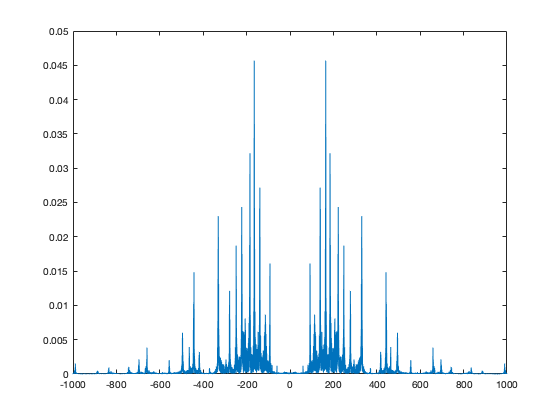

figure(1)
plot(f,abs(X_TF_R));
xlim([-1000 1000]);

## Vamos ouvir a faixa de violão 

sound(R,fs);

## Primeira Aflição: Ruído Branco 

N=wgn(Np,1,1);     % Gera um vetor Ruido 

% Gera o vetor violao sujo
RN=(0.01*N)+R;

% Determina as TF do Ruido e do violao ruidoso

X_DFT_N=fft(N);
X_DFT_RN=fft(RN);

X_TF_N=(1/fs)*fftshift(X_DFT_N);
X_TF_RN=(1/fs)*fftshift(X_DFT_RN);

## Plot da TF do sinal do violão 

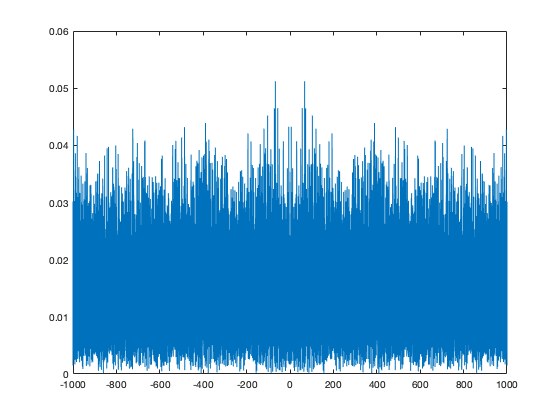

figure(2)
plot(f,abs(X_TF_N));
xlim([-1000 1000]);

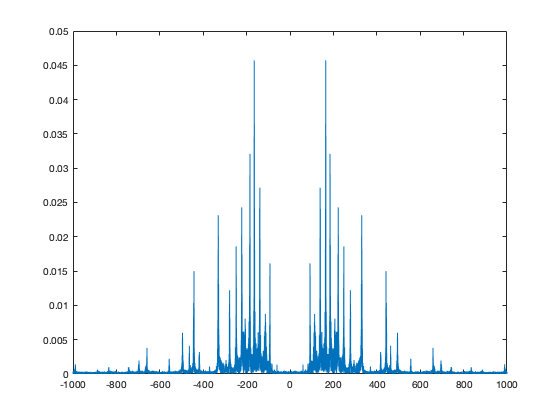


figure(3)
plot(f,abs(X_TF_RN));
xlim([-1000 1000]);

## Vamos ouvir a faixa de violão 

sound(RN,fs);

## Processamento

Agora iremos processar o sinal com auxílio do Filter Design Tool. 

Como é visível no primeiro plot, a faixa possui espectro aproximadamente contido entre 50 e 1kHz.

Estes serão os parametros do filtro, um BandPass.

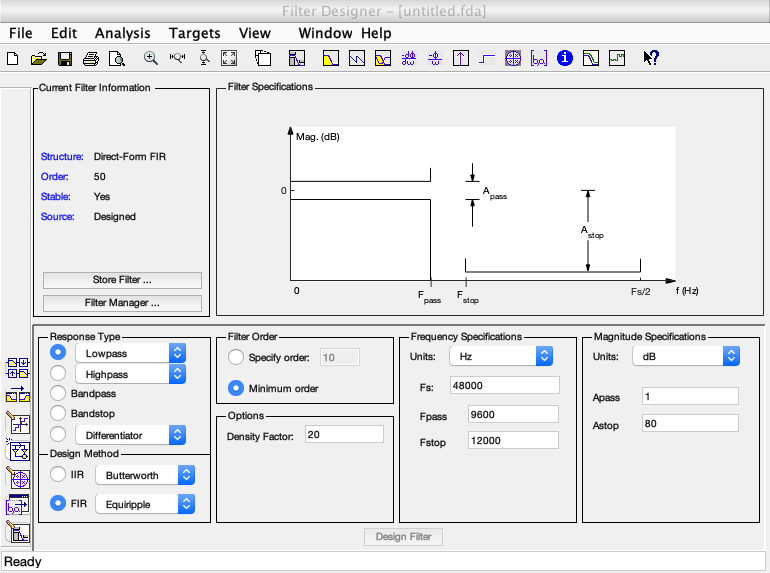

filterDesigner;

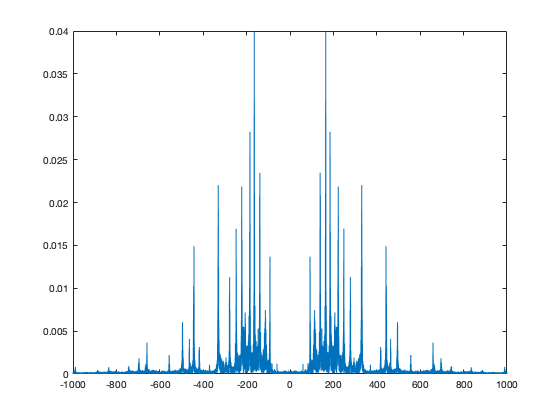

RN=filter(H1,RN);
sound(RN,fs);

% Determina TF do sinal processado 

X_DFT_RN=fft(RN);

X_TF_RN=(1/fs)*fftshift(X_DFT_RN);

% Plota

figure(4)
plot(f,abs(X_TF_RN));
xlim([-1000 1000]);

## Segunda Aflição: Ruído Hum

Ruído Hum é o nome dado ao ruído de fonte, de 60 ou 120 Hz em redes como as brasileiras.

Por vezes uma fonte mal projetada deixa vazar ruído nos canais de áudio.

clear N RN X_DFT_N X_DFT_RN X_TF_N X_TF_RN;

N=cos(2*pi*60*x);     % Gera um vetor Ruido Hum
N=N';

% Gera o vetor violao sujo
RN=(0.05*N)+R;

% Determina as TF do Ruido e do violao ruidoso

X_DFT_N=fft(N);
X_DFT_RN=fft(RN);

X_TF_N=(1/fs)*fftshift(X_DFT_N);
X_TF_RN=(1/fs)*fftshift(X_DFT_RN);

## Plot da TF do sinal do violão 

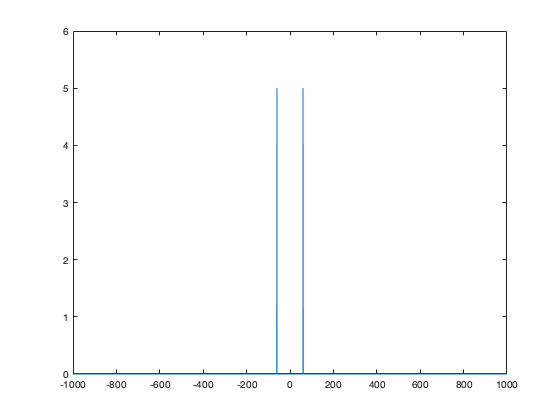

figure(5)
plot(f,abs(X_TF_N));
xlim([-1000 1000]);

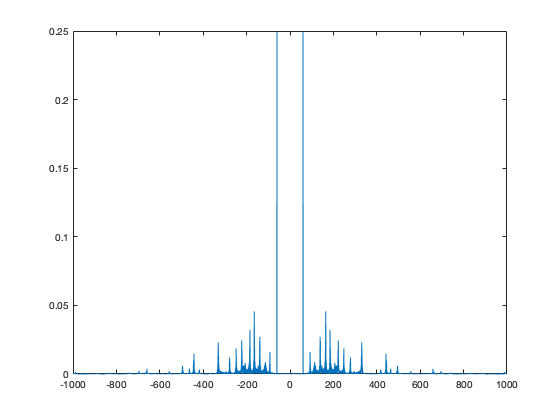


figure(6)
plot(f,abs(X_TF_RN));
xlim([-1000 1000]);

## Vamos ouvir a faixa de violão 

sound(RN,fs);

## Processamento

Agora iremos processar o sinal com auxílio do Filter Design Tool. 

O ruído possui 60Hz e a banda do sinal começa por volta de 50Hz. Perderemos alguma porção dos graves.

Ainda assim, melhoraremos bastante o áudio com um HighPass em 100Hz.

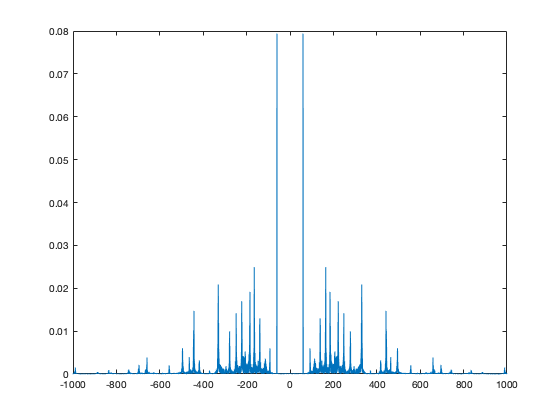

% Hanning; N=250; Fc=150

RN=filter(H1,RN);
sound(RN,fs);

% Determina TF do sinal processado 

X_DFT_RN=fft(RN);

X_TF_RN=(1/fs)*fftshift(X_DFT_RN);

% Plota

figure(7)
plot(f,abs(X_TF_RN));
xlim([-1000 1000]);

## Terceira Aflição: Ruído Hiss

Ruído Hum é o nome dado ao ruído gerado através de interferencias eletromagnéticas.

Estúdios localizados em instalações mal dimensionadas e/ou precariamente isoladas estão mais sucetíveis a este ruído.

É muito comum que a fonte deste problema seja cabeamento de baixa qualidade ou em ground loops.

clear N RN X_DFT_N X_DFT_RN X_TF_N X_TF_RN;

load('Hhiss.mat');

N=wgn(Np,1,1);      % Gera um vetor Ruido 
N=filter(Hhiss,N);  % Faz o ruido hiss

% Gera o vetor violao sujo
RN=(0.1*N)+R;

% Determina as TF do Ruido e do violao ruidoso

X_DFT_N=fft(N);
X_DFT_RN=fft(RN);

X_TF_N=(1/fs)*fftshift(X_DFT_N);
X_TF_RN=(1/fs)*fftshift(X_DFT_RN);

## Plot da TF do sinal do violão 

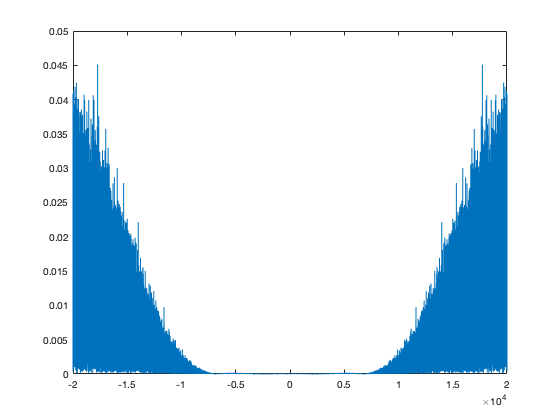

figure(8)
plot(f,abs(X_TF_N));
xlim([-20000 20000]);

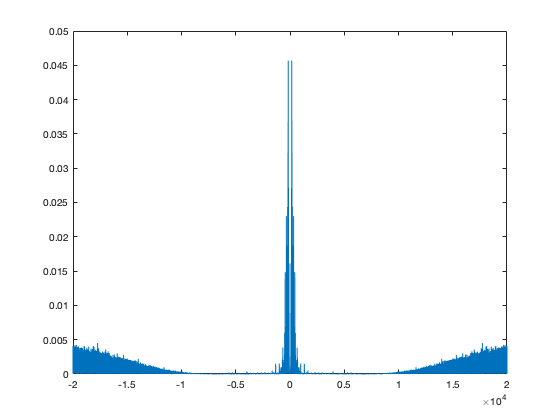


figure(9)
plot(f,abs(X_TF_RN));
xlim([-20000 20000]);

## Vamos ouvir a faixa de violão 

sound(RN,fs);

## Processamento

Agora iremos processar o sinal com auxílio do Filter Design Tool. 

O ruído possui é de alta frequencia e nossa banda está aproximadamente limitada em 1kHz.

Recuperaremos o violão com um LowPass cortando em 2kHz.

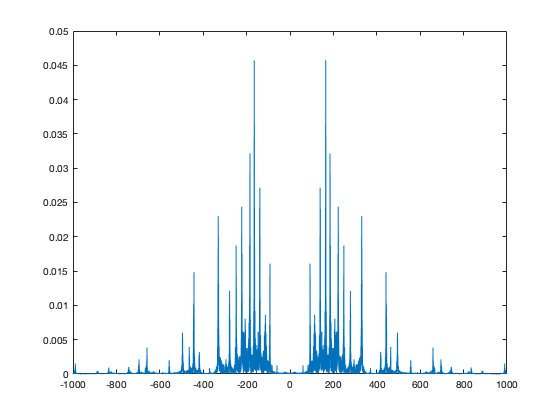

% Blackman; N=100; Fc=2000;

RN=filter(H1,RN);
sound(RN,fs);

% Determina TF do sinal processado 

X_DFT_RN=fft(RN);

X_TF_RN=(1/fs)*fftshift(X_DFT_RN);

% Plota

figure(7)
plot(f,abs(X_TF_RN));
xlim([-1000 1000]);